 A = [0 1 0
     0 0 1
     -4 -5 -7]

A =      0     1     0
     0     0     1
    -4    -5    -7


 B = [0 
     0 
     1]

B =      0
     0
     1


 C = [8 6 2]

C =      8     6     2


 A1 = [0 0 -4
     1 0 -5
     0 1 -7]

A1 =      0     0    -4
     1     0    -5
     0     1    -7


 B1 = [8
     6
     2]

B1 =      8
     6
     2


 C1 = [0 0 1]

C1 =      0     0     1


[P, Z] = jordan(A);
[P1,Z1] = cdf2rdf(P,Z);
Aj = P1^(-1)*A*P1;
Bj = P1^(-1)*B;
Cj = C*P1;
P

P =    0.0251 + 0.0000i  -0.9813 - 1.2344i  -0.9813 + 1.2344i
  -0.1585 + 0.0000i  -0.5457 + 1.1310i  -0.5457 - 1.1310i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Z

Z =   -6.3079 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3461 - 0.7172i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3461 + 0.7172i


simtime = 10

simtime = 10

first = sim("Task2.slx", simtime)

first =   Simulink.SimulationOutput:

                     in: [1x1 timeseries] 
                simout1: [1x1 timeseries] 
                simout2: [1x1 timeseries] 
                simout3: [1x1 timeseries] 
                simout4: [1x1 timeseries] 
                   tout: [59x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


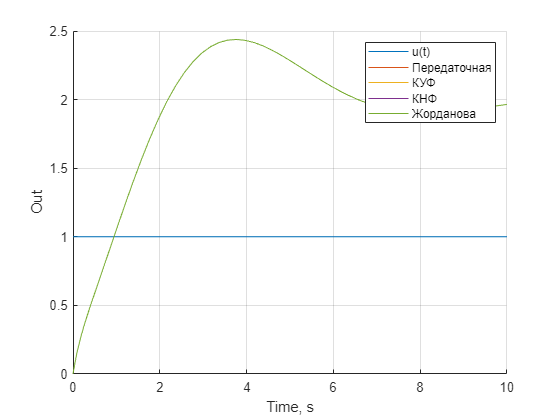

hold on
plot(first.in.Time, first.in.Data)
plot(first.simout1.Time, first.simout1.Data)
plot(first.simout2.Time, first.simout2.Data)
plot(first.simout3.Time, first.simout3.Data)
plot(first.simout4.Time, first.simout4.Data)

xlabel("Time, s")
ylabel("Out")
grid on
legend(["u(t)","Передаточная","КУФ","КНФ","Жорданова"])

Cj

Cj =     1.2499  -12.9046   -4.3693


кун


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-4 & -5 & -7
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
8 & 6 & 2
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack 
\end{array}$$


кнф


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & -4\\
1 & 0 & -5\\
0 & 1 & -7
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
8\\
6\\
2
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack 
\end{array}$$


жорд


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-6\ldotp 3079 & 0 & 0\\
0 & -0\ldotp 3461 & -0\ldotp 7172\\
0 & 0\ldotp 7172 & -0\ldotp 3461
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\ldotp 10358\\
-0\ldotp 0732\\
0\ldotp 0741
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
1\ldotp 2499 & -12\ldotp 9046 & -4\ldotp 3693
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack 
\end{array}$$
